# Solve an Overdetermined System

This code plots the lines.

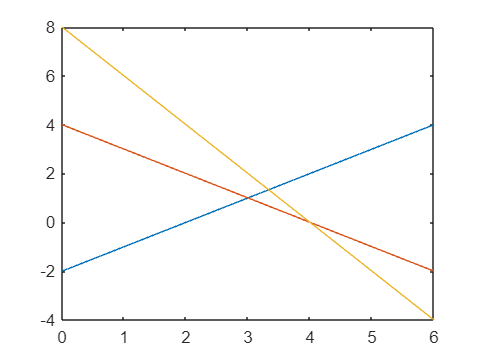

x = linspace(0,6);
plot(x,x-2)
hold on
plot(x,4-x)
plot(x,8-2*x)
hold off

## Task 1

In this activity, you will solve an overdetermined  system of equations. The equations can be visualized as three lines, and the lines have been plotted for you. By examining the plot, you can see that the three lines do not all intersect at a single point.

Consider the following system of equations:

x−y=2

x+y=4

2x+y=8

Task

Make a 3-by-2 matrix containing all the coefficients. Name this matrix `A`. 

The first column should be the xcoefficients, and the second column should be the ycoefficients.

A=[1 -1;
    1 1;
    2 1]

A =      1    -1
     1     1
     2     1


## Task 2

The system of equations is

x−y=2

x+y=4

2x+y=8

Task

Assemble the constants on the right side of the equations into a column vector named `b`.

b=[2 4 8]'

b =      2
     4
     8


## Task 3

You can solve for **x** using the backslash operator (`\`). Because the system is overdetermined, `\` will try to find the best solution using least squares.

Task

Solve for **x** using the command `A``\``b`. Assign the output to a variable `point`.

point=A\b

point =     3.2857
    1.1429


## Task 4

The variable `point` is a two-element vector. The first element is the x value of the solution, and the second element is the y value of the solution.

Task

Plot the point (`point``(``1``)`,`point``(``2``)`) as a circle marker in the existing figure using the `hold` `on` command.  

Remember to use the `hold` `off` command when you're finished adding to your plot. 

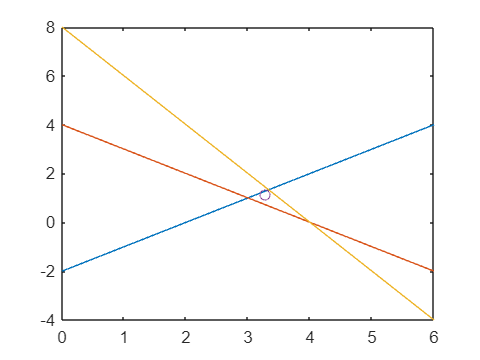

hold on
plot(point(1),point(2),"o")
hold off

## Further Practice

Although there was no exact solution for this system of equations, you could  still use the backlash operator to find a best-fit solution (the values  that give the least overall error). 

You can see how close the result is to solving each of the equations by calculating `A``*``point` and comparing it to `b`.

A*point

ans =     2.1429
    4.4286
    7.7143


b

b =      2
     4
     8
